clearvars
addpath("kwave/");
addpath("ISM/");

### Parameter Initialisation

% -------------------------
% --------- Grid ----------
dimension = [32,32,32]; % Computational grid x and y dimensions
spacing = 1; % (m) Spacing between each point of the grid
Nt = 30000; % Number of timesteps
dt = 0.0001; % (s) Size of timesteps
% -------------------------
% ------ Positions --------
p_source = [0,0,0]; % (x,y,t) Source coordinates
p_receiver = [-8,0,0]; % (x,y,z) Receiver coordinates
% -------------------------
% ---- Wave Equation ------
c = 343; % (m/s) Speed of sound
frequency = 150; % Signal frequency in Hz
alpha = [0,0,0,0,0,0]; % Absorption coefficient
U0 = 3.75; % Radial velocity
a = 0.01; % Radius of emitting sphere
Q = 4*pi*a^2*U0; % Source strength
rho = 1.125; % Density of air
% -------------------------

### Kwave

Running k-Wave simulation...
  start time: 12-Nov-2021 08:54:05
  reference sound speed: 343m/s
  dt: 100us, t_end: 2.9999s, time steps: 30000
  input grid size: 32 by 32 by 32 grid points (32 by 32 by 32m)
  maximum supported frequency: 171.5Hz
  precomputation completed in 0.16569s
  starting time loop...
  estimated simulation time 6min 16.6206s...


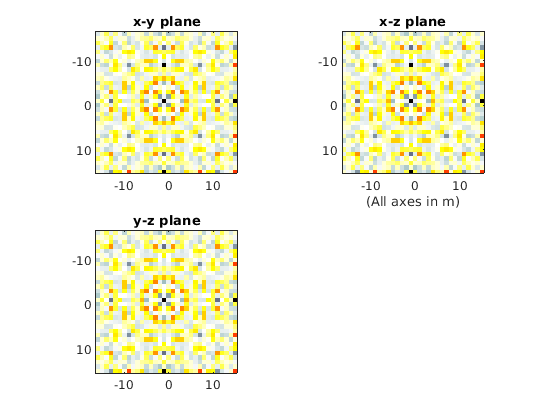

  simulation completed in 9min 0.42866s
  total computation time 9min 0.62637s


[t_array,scale,prefix,in_p,kwave_out_p] = monopole_sound_source(p_source,p_receiver,frequency,dimension,spacing,Nt,dt,alpha);

### Image Source Method

order = 18;
[~, ism_out_p] = image_source_pressure_wave(p_source,p_receiver,dimension,t_array,spacing,c,frequency,Q,rho,order,alpha,0);

### Plotting

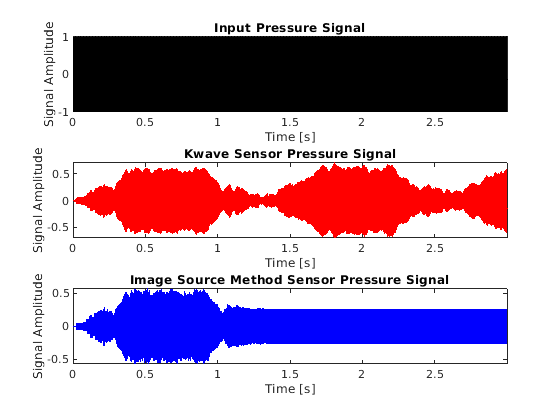

figure;
% -------- Input pressure ---------
subplot(3, 1, 1);
plot(t_array * scale, in_p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Input Pressure Signal');
% ------------ Kwave ---------------
subplot(3, 1, 2);
plot(t_array * scale, kwave_out_p, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Kwave Sensor Pressure Signal');
% ------ Image Source Method -------
subplot(3, 1, 3);
plot(t_array * scale, ism_out_p, 'b-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Image Source Method Sensor Pressure Signal');

### Difference between kwave and image source implementation

diff = abs(ism_out_p - kwave_out_p);
figure;
new_ism_out_p = [0 ism_out_p(1:end-1)];
diff = abs(new_ism_out_p - kwave_out_p);
mean(diff)

ans = 0.0135

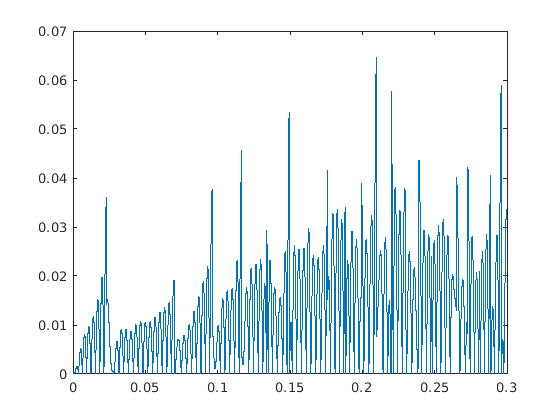

plot(t_array,diff);